Summary_csv_path = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/New_empirical_csv_20230414/'

Summary_csv_path = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/New_empirical_csv_20230414/'

timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

FilePostFix = '_20230414_backcorr';

cd('/Volumes/PcSSDA/RvR/20220325_1610_RvR_001')
ExperimentName='20220325_1610_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

FilePostFix = '_20230414';

global PeakGeneralization PostPeakChannels
PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;


background_all = zeros(1,3);

for i = 1:3
    SpcFileLoad = load([ExperimentName, 'FLIM00', num2str(i), '.mat']);
    background_all(i) = sum(SpcFileLoad.spcSave.lifetimes{1})
end

global backcorr BackGroundCorrection

backcorr = round((mean(background_all))/256)

BackGroundCorrection = 1;

i = 1;
filename_new=[analysis_name,num2str(i),'_20230414', '.mat'];
load(filename_new)

histogram_normalization = lifetime_histograms./max(lifetime_histograms);
histogram_mean = mean(histogram_normalization');
eval(['histogram_mean_', mouse, '= histogram_mean;'])

global PeakChannelSet

PeakChannelSet = find(histogram_mean == max(histogram_mean))

FLP_analysis_script


filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

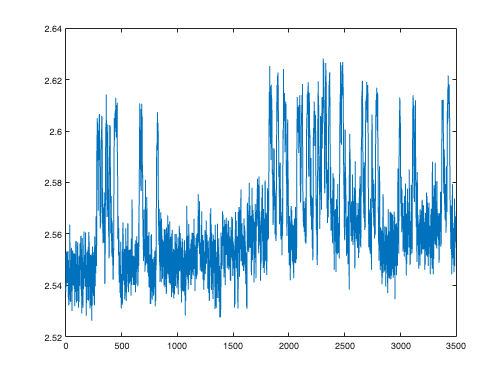

figure
plot(tau_empTrunc)

resting_index = 42:1:244;
running_index = 280:1:293;

histogram_resting = lifetime_histograms(:, resting_index);
histogram_running = lifetime_histograms(:, running_index);


histogram_resting_norm = histogram_resting./max(histogram_resting);
histogram_running_norm = histogram_running./max(histogram_running);

histogram_resting_mean = mean(histogram_resting_norm');
histogram_running_mean = mean(histogram_running_norm');



colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220325_1610_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])

movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['speed.csv/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName])

cd('/Volumes/PcSSDA/RvR/20220330_1610_RvR_003')
ExperimentName='20220330_1610_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220330_1610_RvR_003_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName])

cd('/Volumes/PcSSDA/RvR/20220325_1611_RvR_001')
ExperimentName='20220325_1611_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels

% FLP_analysis_script

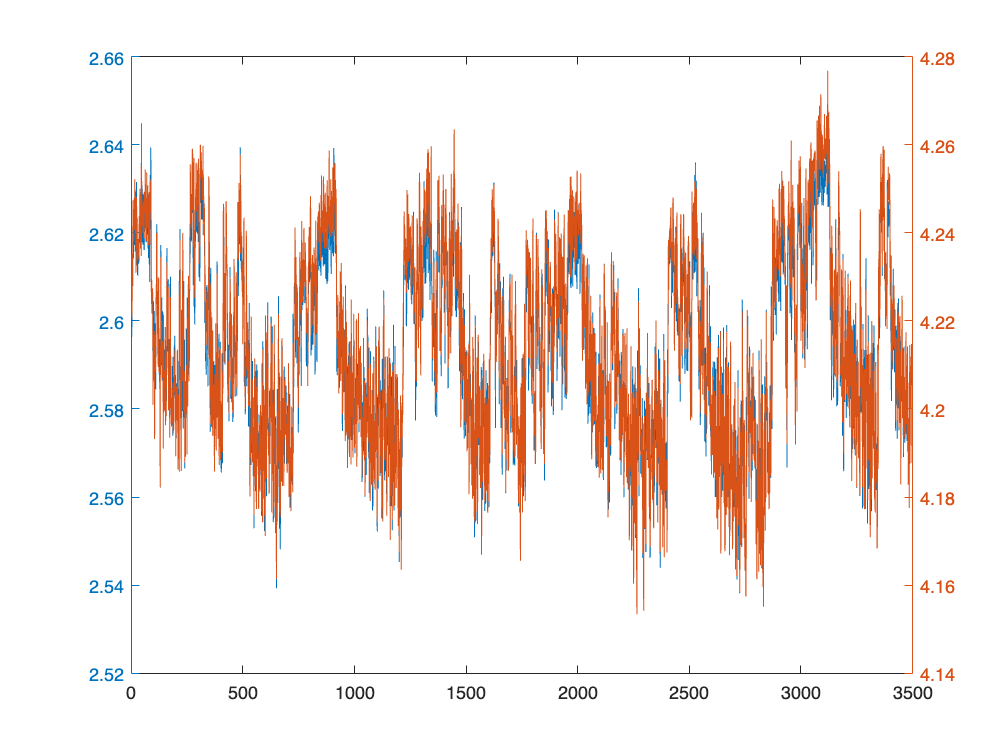

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

tau_new = tau_empTrunc;

filename=[analysis_name,num2str(1),'_20220403.mat'];
load(filename)

tau_old = tau_empTrunc;

figure
yyaxis right
plot(tau_old)
yyaxis left
plot(tau_new)

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)

FLP_all = 3495×4 table
     time     intensity     tau_empirical    tau_fit
    ______    __________    _____________    _______

     1.012    2.1754e+05       2.6096        2.5258 
     2.472    2.1599e+05       2.5964        2.5121 
     3.492    2.1416e+05       2.6131         2.505 
     4.512    2.1298e+05       2.6095        2.5184 
     5.533    2.1296e+05       2.6093        2.4967 
     6.553    2.1542e+05        2.608        2.5421 
     7.573    2.1836e+05       2.6265        2.5438 
     8.593    2.1744e+05       2.6167        2.5313 
     9.612    2.1763e+05       2.6142        2.5319 
    10.632    2.1748e+05       2.6158        2.5338 
    11.653    2.1828e+05       2.6187        2.5452 
    12.672    2.1904e+05       2.6182        2.5623 
    13.692    2.1992e+05       2.6233        2.5314 
    14.712    2.1922e+05       2.6173        

FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220325_1611_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])

Unrecognized function or variable
'Summary_csv_path'.

movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['timestamp_speed/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220331_1611_RvR_002')
ExperimentName='20220331_1611_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220331_1611_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220325_1612_RvR_001')
ExperimentName='20220325_1612_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220325_1612_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['timestamp_speed/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220330_1612_RvR_002')
ExperimentName='20220330_1612_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220330_1612_RvR_002_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220329_1626_RvR_001')
ExperimentName='20220329_1626_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220329_1626_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220328_1629_RvR_001')
ExperimentName='20220328_1629_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220328_1629_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220404_1629_RvR_002')
ExperimentName='20220404_1629_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220404_1629_RvR_002_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220404_1629_RvR_003')
ExperimentName='20220404_1629_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220404_1629_RvR_003_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220328_1630_RvR_001')
ExperimentName='20220328_1630_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220328_1630_RvR_001_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220404_1630_RvR_002')
ExperimentName='20220404_1630_RvR_002'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220404_1630_RvR_002_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])

cd('/Volumes/PcSSDA/RvR/20220404_1630_RvR_003')
ExperimentName='20220404_1630_RvR_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];

PeakGeneralization = 1; % 'PeakGeneralization' method
PostPeakChannels = 150;
global PeakGeneralization PostPeakChannels
FLP_analysis_script

filename=[analysis_name,'1',FilePostFix,'.mat'];
load(filename)

colnames={'time','intensity','tau_empirical','tau_fit'}

colnames = 1×4 cell array
    {'time'}    {'intensity'}    {'tau_empirical'}    {'tau_fit'}


FLP_all=table(time, photoncount, tau_empTrunc, tau_avg, 'VariableNames',colnames)
FLP_all_csv=[ExperimentName,'_FLP.csv']

FLP_all_csv = '20220404_1630_RvR_003_FLP.csv'


writetable(FLP_all, FLP_all_csv)

mkdir([Summary_csv_path, ExperimentName])
movefile(FLP_all_csv, [Summary_csv_path, ExperimentName])
movefile(['data/', ExperimentName, '_speed0.csv'], [Summary_csv_path, ExperimentName, '/', ExperimentName, '_speed.csv'])